# Assignment 2 in Modsim

#### By Alexander Brevad Rambech

### Task 1

**a)**

The definition of $SO(3)$ is given by:

- 
$$SO(3) = \{R : R \in \rm I\!R^{3\times3}, ~ R^TR = I,~det(R)=1\}$$


by this definition the columns in the $R$ matrices have to be orthogonal. This means that the scalar product between each column vector must be equal to zero. This results in the following matrices:

- $R_1 = \left[ \matrix{0~ & 1 & 0 \cr 1~ & 0 & 0 \cr 0~ & 0 & -1} \right]$and $R_2 = \left[ \matrix{\frac{5}{13}~ & 0 & -\frac{12}{13} \cr 0~ & 1 & 0 \cr \frac{12}{13}~ & 0 & \frac{5}{13}} \right]$

This can be double checked using the right hand rule.

**b)**

Given the rotation matrix $R_b^a$, a vector $v$ in frame $a$ is given by:

- 
$$v^a = R^b_a v^b$$


From this it follows that $R_b^a
$ can be written as:

- 
$$R_b^a = \left[ \matrix{a_1 \cdot b_1 & a_1 \cdot b_2 & a_1 \cdot b_3 \cr a_2 \cdot b_1 & a_2 \cdot b_2 & a_2 \cdot b_3 \cr a_3 \cdot b_1 & a_3 \cdot b_2 & a_3 \cdot b_3} \right]$$


here we see that the first column is the first element of $v^b$ vector in the $a
$ frame. The rest follows accordingly.

**c) **

- 
$$(v^a)^Tv^a = (v^b)^T(R_b^a)^TR_b^a v^b = (v^b)^TIv^b = (v^b)^T v^b$$
 

**d)**

- 
$$u^a \times v^a = (R^a_bu^b) \times (R_b^a v^b)$$


From this we use the skew-symmetric matrix $(Ru)^\times$

- 
$$\Rightarrow (R_b^au^b)^\times(R_b^av^b) = (R_b^au^b)^\times(R_b^a)^TR_b^av^b = R_b^a(u^b)^\times (R_b^a)^TR_b^av^b=R_b^a(u^b \times v^b)$$


The relation shows that it is the same if we cross then rotate or rotate then cross.

### **Task 2**

**a)**

%% SymbolicEuler
clear all
close all
clc

%%% FILL IN ALL PLACES LABELLED "complete"

syms rho theta psi real
syms drho dtheta dpsi real

A     = [rho;theta;psi];
dA    = [drho;dtheta;dpsi];


% rotation about x
R{1} = [1 0 0;
        0 cos(A(1)) -sin(A(1));
        0 sin(A(1)) cos(A(1))];

% rotation about y
R{2} = [cos(A(2)) 0 sin(A(2));
        0 1 0;
        -sin(A(2)) 0 cos(A(2))];

% rotation about z
R{3} = [cos(A(3)) -sin(A(3)) 0;
        sin(A(3)) cos(A(3)) 0;
        0 0 1];

%Rotation matrix
Rba = simplify(R{1}*R{2}*R{3});

% Time deriviatve of the rotation matrix (Hint: use the function "diff"
% (the one from the Symbolic Math Toolbox) to differentiate the matrix w.r.t. the
% angles rho, theta, psi one by one, and form the whole time derivative using the
% chain rule and summing the deriviatives)
dRba = simplify(diff(Rba,A(1))*dA(1) + diff(Rba,A(2))*dA(2) + diff(Rba,A(3))*dA(3))

% Use the formulat relating Rba, dRba and Omega (skew-symmetric matrix
% underlying the angular velocity omega)
Omega =(Rba'*dRba); % Is on the form [ 0  -w_3  w_2;
                                    % w_3   0  -w_1;
                                    %-w_2  w_1   0];


% Extract the angular veloticy vector omega (3x1) from the matrix Omega (3x3)
omega = [Omega(3, 2); % omega_1
         Omega(1, 3); % omega_2
         Omega(2, 1)] % omega_3 

% This line generates matrix M in the relationship omega = M*dA
M = jacobian(omega,dA);

% This line creates a Matlab function returing Rba and M for a given
% A  = [rho;theta;psi], can be called using [Rba,M] = Rotations(state);
matlabFunction(Rba,M,'file','Rotations','vars',{A})

Code works and creates the "Rotations" function

**b)**

The inside of the implemented "Kinematics" function is given by:

%% Kinematics    
    % Code your equations here...
    euler_params = parameters;      % Is the current angular velocity
    [R, M] = Rotations(state);     % Takes current state as argument
    %dx = M\euler_params;        % Modelled dynamics of the system
    
    state_dot = M\euler_params;

The angular velocity is given by $\omega_{ab}^b = M \left[\matrix{\dot{\rho} \cr \dot{\theta} \cr \dot{\phi}} \right]$, to model the dynamics we solve forthe state derivatives and obtain $\left[\matrix{\dot{x}_1 \cr \dot{x}_2 \cr \dot{x}_3} \right] = \left[\matrix{\dot{\rho} \cr \dot{\theta} \cr \dot{\phi}} \right] = M^{-1}\omega_{ab}^b$

**c)**

Hit a key to start animation


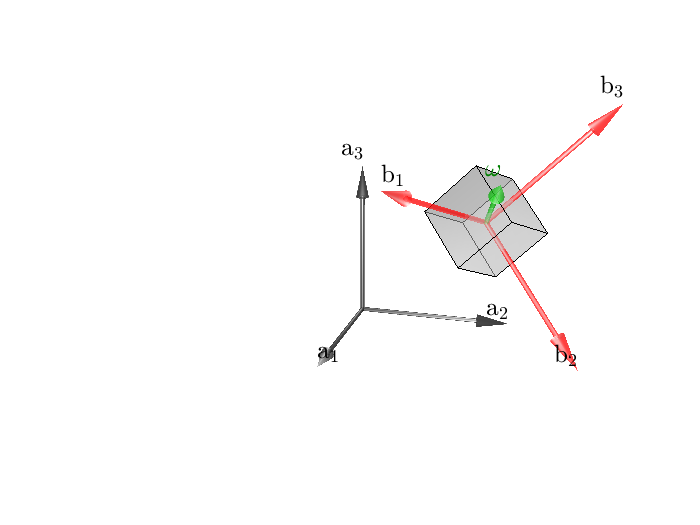

%% MainKinematics
clear all
close all
clc

time_final = 20; %Final time

%%%%%% MODIFY. Initial state values and parameter values
init_state = [0;0;0]; % We start with zero as initial angle
parameters = [3;1;2]; % We start with zero velocity

% Simulate dynamics
try
    %%%%%% MODIFY THE FUNCTION "Kinematics" TO PRODUCE SIMULATIONS OF THE SOLID ORIENTATION
    %%%%%%
    %%%%%% Hints:
    %%%%%% - "parameters" allows you to pass some parameters to the "Kinematic" function.
    %%%%%% - "state" will contain representations of the solid orientation (SO(3)).
    %%%%%% - use the "reshape" function to turn a matrix into a vector or vice-versa.
    
    [time,statetraj] = ode45(@(t,x) Kinematics(t, x, parameters), [0,time_final], init_state);

catch message
    display('Your simulation failed with the following message:')
    display(message.message)
    display(' ')

    %Assign dummy time and states if simulation failed
    time = [0,10];
    statetraj = [0,0];
end

%Below is a template for a real-time animation
ScaleFrame = 5;   % Scaling factor for adjusting the frame size (cosmetic)
FS         = 15;  % Fontsize for text
SW         = 0.035; % Arrows size

time_display = 0; % initialise time_display
while time_display < time(end)

    state_animate = interp1(time,statetraj,time_display); %interpolate the simulated state at the current clock time

    p     = [5;5;5];  % Position of the single body

    %%%%%% MODIFY THE FOLLOWING LINES TO PRODUCE AN "omega" AND "R" FROM YOUR SIMULATION STATE

    %omega = [0;0;4];  % Some random Omega

    %R     = [   -0.8603    0.4343   -0.2670
     %           -0.4771   -0.8705    0.1213
      %          -0.1797    0.2317    0.9560]; % Some random rotation matrix
    
    omega = parameters; % Fetches parameters from ODE45
    R = Rotations(state_animate.'); % Fetches animation states and transforms the frame from b to a
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %3D below this point
      figure(1);clf;hold on
    MakeFrame( zeros(3,1),eye(3),ScaleFrame,FS,SW,'a', 'color', 'k')
    MakeFrame( p,R,ScaleFrame,FS,SW,'b', 'color', 'r')
    MakeArrow( p,R*omega,FS,SW,'$$\omega$$', 'color', [0,0.5,0])
    DrawRectangle(p,R ,'color',[0.5,0.5,0.5]);
    FormatPicture([0;0;2],0.5*[73.8380   21.0967   30.1493])

    if time_display == 0
        display('Hit a key to start animation')
        pause
        tic
    end
    time_display = toc; %get the current clock time
end

**d)**

The results seem reasonable because the axis of rotation stayes the same inn every simulation, with only the magnitude of $\omega_{ab}^b$ changing.

### Task 3

**a) **

- 
$$Rk = (cos(\theta)I + sin(\theta)k^\times + (1-cos(\theta)kk^T)k = cos(\theta)Ik + sin(\theta)k^\times k + Ik-cos(\theta)Ik = k$$


**b)**

Shepperd's algorithm for finding Euler parameters using rotation matrices can be found in the Modeling and Simulation text book. Written out in code it is:

## Shepperd's algorithm

function [theta, k] = R_to_k_and_theta(R)
    r11 = R(1, 1);
    r22 = R(2, 2);
    r33 = R(3, 3);
    r00 = r11 + r22 + r33 % Trace of R
    % I didn't really figure this one out
end